# Optimization Under Uncertainty

## Goals

- **Connect the Bridge between Parameter Estimation and Optimization:** Discuss why robust and accurate parameter estimation is essential to execute reliable optimization. 

- **Optimization Under Uncertainty:** Reformulate an existing optimization framework to utilize profile likelihood confidence intervals explicitly.

- **Walk-Through:** Offer a simple, step-by-step guide to performing optimization under uncertainty

## High-Level Highlights

We join the parameter estimation approach introduced in Parameter Estimation via Profile Likelihoods and the surrogate model-based optimization framework discussed in Surrogate Model-Based Optimization to achieve an optimization solution under uncertain modeling parameters. Specifically, we explicitly use the parameter estimation's confidence intervals to perform constrained optimization over a distribution of possible outcomes. The plots below summarize the result of the approach. The "worst-case scenario" is accurately predicted. At the same time, the imposed constraint is satisfied for all evaluated cases. As discussed in previous articles, this workflow relies on many system model evaluations and only becomes feasible using surrogate models and surrogate model-based optimization techniques. 

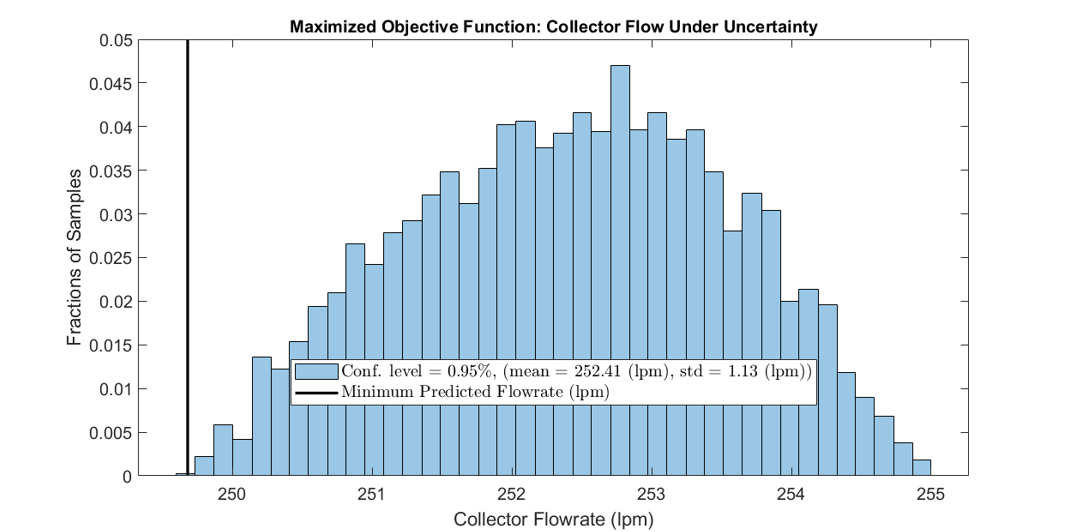

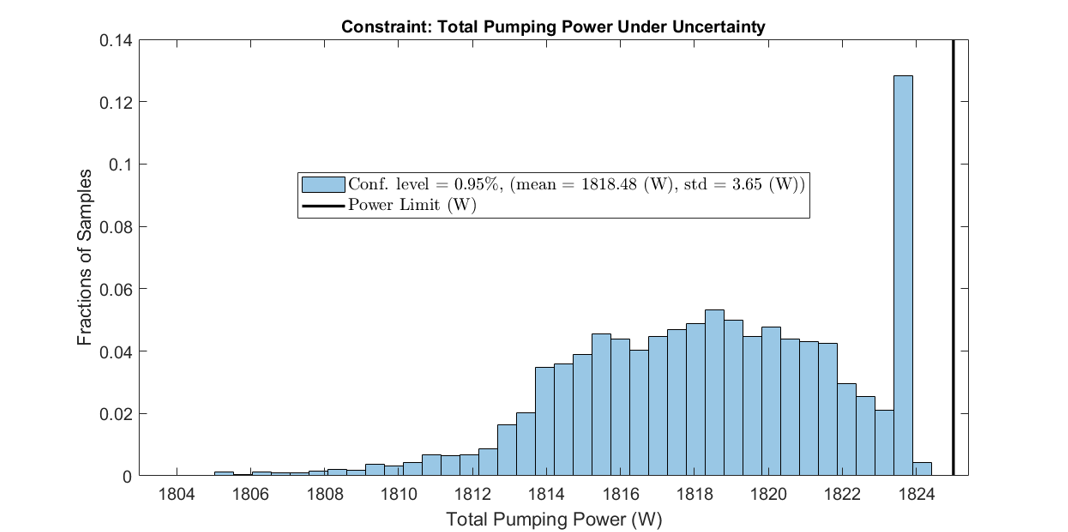

## Optimization Under Uncertain Fixed Variables 

The optimization framework introduced in Surrogate Model-Based Optimization distinguishes between decision and fixed variables. Fixed variables are surrogate model inputs that are not directly controlled but are essential to describe the system's behavior. For example, ambient temperature in a building heating system would be a fixed variable. However, fixed variables may need to be estimated and, in some cases, only partially known. That is, the exact value of some fixed variables may not be available. As a result, the optimized system's performance will deviate from its predicted behavior. 

Consider the small-scaled optimization problem given by Example 1 in Surrogate Model-Based Optimization. Suppose the source pressures' estimates (lines 1-4) are 1.0 atm but uncertain. Let's assume the source pressures can take on a range of values with a minimum and maximum of 0.8 atm and 1.2 atm, respectively. Further, we shall constrain the total pumping power to under 200 Watts. We then optimize only considering the nominal case where pressures equal 1.0 atm. The first plot shows how the actual collector flow rate will deviate from the predicted flow rate when pressures are allowed to take values different from the nominal case. Since we only considered the nominal case, the resulting system performance cannot be accurately assessed. Furthermore, the second plot shows that the system will violate the pumping power constraint under some off-nominal source pressures (about 15 percent of cases). 

These findings underscore the inherent unpredictability and potential for undesirable outcomes stemming from uncertainty in fixed variables. In the next section, we incorporate this uncertainty into the optimization framework to produce more robust and reliable results.

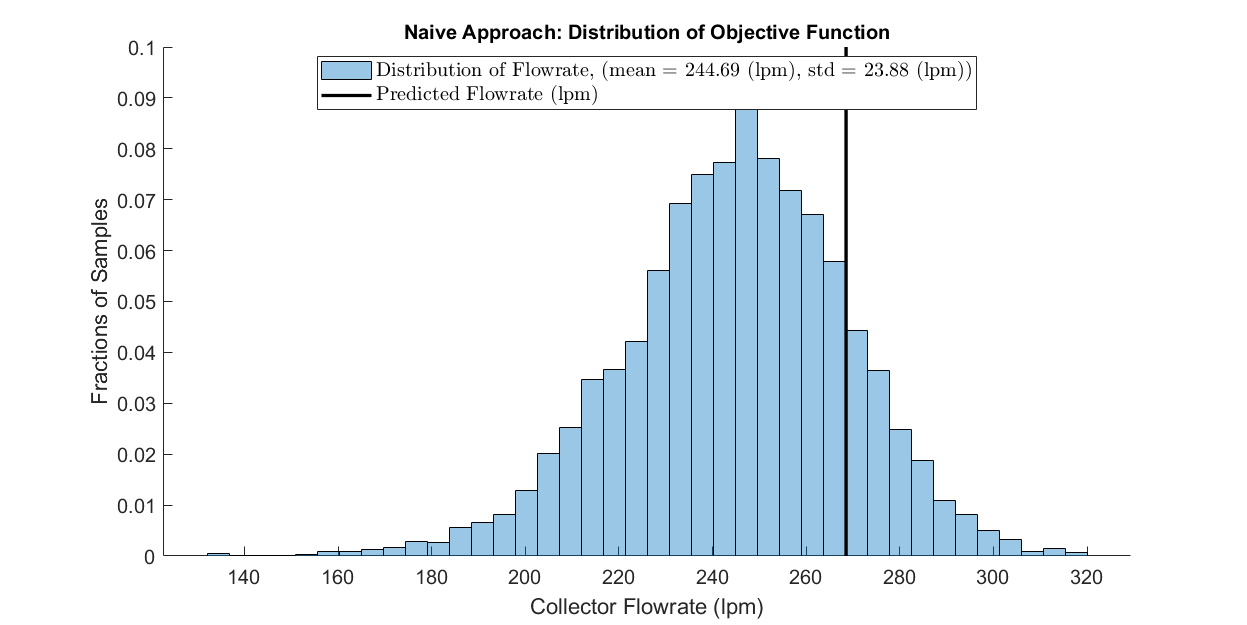

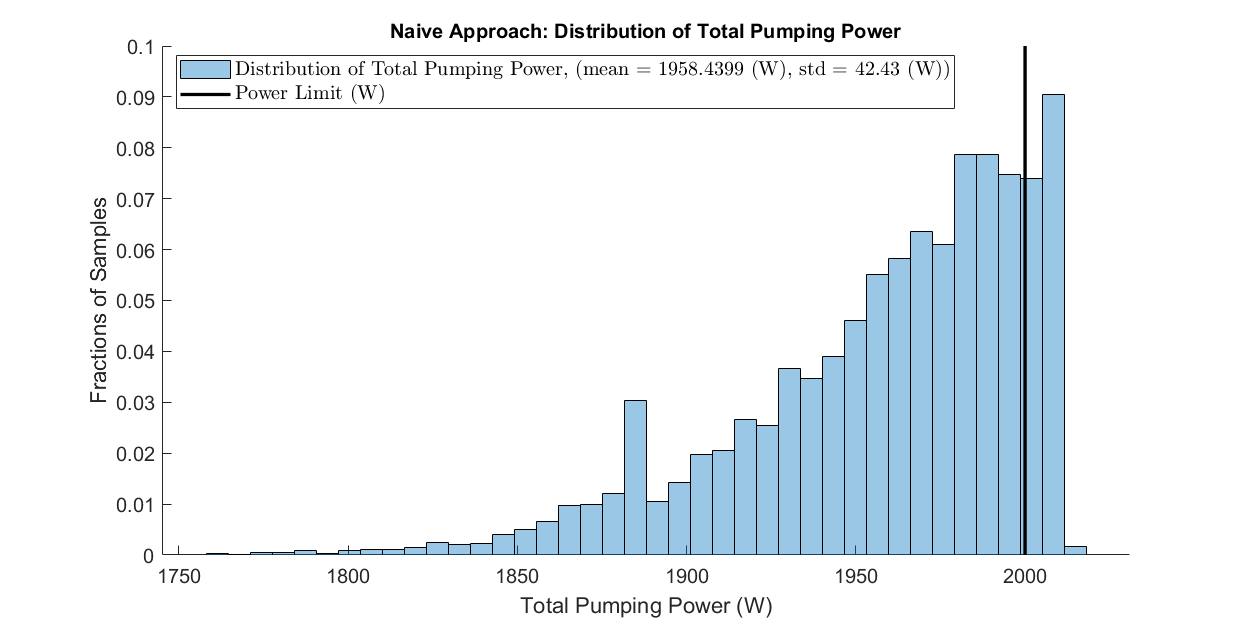

## Reformulate the Optimization Framework

We now reformulate the surrogate model-based optimization framework introduced in Surrogate Model-Based Optimization to explicitly consider uncertainty in fixed variables. Recall we formulated the surrogate model-based optimization problem as follows:


$$\ \text{given }p, \  \max_{x_{\text{decision}}}{f(\text{surrogate}(x_{\text{decision}},x_{\text{fixed}}))}\ \text{subject to} \ g(\text{surrogate}(x_{\text{decision}},x_{\text{fixed}}))\leq0 \ \text{and} \ x_{\text{fixed}} = p.

$$
  

where $f()
$ is the objective function to maximize, $g()
$ describes a set of constraints, $x_{\text{decision}}
$ are the inputs to be optimized, and $x_{\text{fixed}}
$ are fixed variables. In addition, $\text{surrogate}()$ is included to indicate that the execution of the surrogate model is needed to evaluate the objective and constraint functions. We now introduce the set of all possible fixed variable values for a given confidence level $
\alpha$,    


$$P_\alpha = \{ x_\text{fixed}^1,x_\text{fixed}^2,\dots.\}.

$$


We will approximate the infinite set $P_\alpha


$ with a finite set $\bar{P}_\alpha

$ (discussed in the next section). We now incorporate the set $\bar{P}_\alpha

$ into the optimization formulation as follows: 


$$\ \text{given } \bar{P}_\alpha, \  \max_{x_{\text{decision}}}\min({f(\text{surrogate}(x_{\text{decision}},x_{\text{fixed}}))})\ \text{subject to} \ \max(g(\text{surrogate}(x_{\text{decision}},x_{\text{fixed}})))\leq0 \ \text{for all} \ x_{\text{fixed}} \in \bar{P}_\alpha.

$$


Notice that the objective function is the minimum of $f()
$ over all $\bar{P}_\alpha

$. Therefore, we are optimizing the "worst case scenario," and we can expect with confidence level $
\alpha$ that the system will perform at or above the predicted performance. Likewise, we ensure that the maximum value of the constraint function over all $\bar{P}_\alpha

$ is below zero. As a result, with confidence level $
\alpha$, the system will satisfy the constraints given by $g()
$.   

Other variations of this formulation are possible. The minimum function can be replaced by a combination of the objective's mean and variance. In addition, two independent fixed variable sets with different confidence levels can be used for the objective and constraint evaluations (e.g. $\bar{P}_{\alpha_f}

$ and $\bar{P}_{\alpha_g}

$).

### Confidence Intervals for Multiple Parameters

The confidence intervals discussed and shown in Parameter Estimation via Profile Likelihoods were computed for single parameters. We asked: What is our confidence that parameter $\theta

$ lies between $\theta_{min}

$ and $\theta_{max}

$? As shown in [1], the computation is easily extended for multiple parameters. When computing confidence intervals for multiple parameters, we determine the "joint" confidence level for all considered parameters. For example, suppose there are two fixed variables ($\theta =(\theta_1,\theta_2)
$). We can now ask: What is our confidence that parameter $\theta_1

$ lies between $\theta_{1_{min}}

$ and $\theta_{1_{max}}

$ ***and*** parameter $\theta_2

$ lies between $\theta_{2_{min}}

$ and $\theta_{2_{max}}

$? If the parameters are independent, their joint confidence interval will be the product of their individual confidence intervals. However, this will not be the case in most systems, as parameters will exhibit some interdependence. 

## Walk-Through Example

In this section, we walk through an example, starting from estimating parameters using noisy sensor data and ending with an optimized result. The example is based on Example 1 in Surrogate Model-Based Optimization, where the collector flow rate is maximized while limiting the total pumping power. 

### Step 1: Estimate Unknown Parameters

We perform the parameter estimation procedure detailed in Parameter Estimation via Profile Likelihoods. The procedure results in confidence levels for the parameter estimates. It's important to note that the quality of the parameter estimation will directly impact the quality of the optimization. In essence, the more uncertainty present in the fixed variables, the lower the performance the optimization framework can achieve.

The GUI Interface is described in detail in Parameter Estimation via Profile Likelihoods. 

numSamples = 15;
disp('Active Sensors:')

Active Sensors:


collector_flowrate = true;
line_1_pressure = true;
line_2_pressure = true;
line_3_pressure = true;
line_4_pressure = true;
disp('Sensor Noise:')

Sensor Noise:


collector_flowrate_sigma = 0.75;
line_1_pressure_sigma = 0.2;
line_2_pressure_sigma = 0.2;
line_3_pressure_sigma = 0.2;
line_4_pressure_sigma = 0.2;

outputIdx = [];
sigma = [];
if collector_flowrate
    outputIdx(end+1) = 1;
    sigma(end+1) = collector_flowrate_sigma;
end
if line_1_pressure
    outputIdx(end+1) = 3;
    sigma(end+1) = line_1_pressure_sigma;
end
if line_2_pressure
    outputIdx(end+1) = 6;
    sigma(end+1) = line_2_pressure_sigma;
end
if line_3_pressure
    outputIdx(end+1) = 9;
    sigma(end+1) = line_3_pressure_sigma;
end
if line_4_pressure
    outputIdx(end+1) = 12;
    sigma(end+1) = line_4_pressure_sigma;
end

 

%% Generate Random Pressures to Estimate
sp = rand(4,1).*[0.8;0.8;0.8;0.8] + [0.6;0.6;0.6;0.6];
source_pressure.source_pressure_1 = sp(1);
source_pressure.source_pressure_2 = sp(2);
source_pressure.source_pressure_3 = sp(3);
source_pressure.source_pressure_4 = sp(4);

disp('Randomly select source pressures:')

Randomly select source pressures:


disp(['Source 1-4 Pressures (atm): ' num2str(source_pressure.source_pressure_1,'%.2f') ', '...
                                    num2str(source_pressure.source_pressure_2,'%.2f') ', '...
                                    num2str(source_pressure.source_pressure_3,'%.2f') ', '...
                                    num2str(source_pressure.source_pressure_4,'%.2f')])

Source 1-4 Pressures (atm): 1.24, 1.12, 0.60, 0.98


Executing parameter estimation...
Generating Profile Curve for Source Pressure 1
Generating Profile Curve for Source Pressure 2
Generating Profile Curve for Source Pressure 3
Generating Profile Curve for Source Pressure 4
A total of 35691 surrogate model evaluations were executed.
Sensor readings from 15 operational points were used in this analysis.


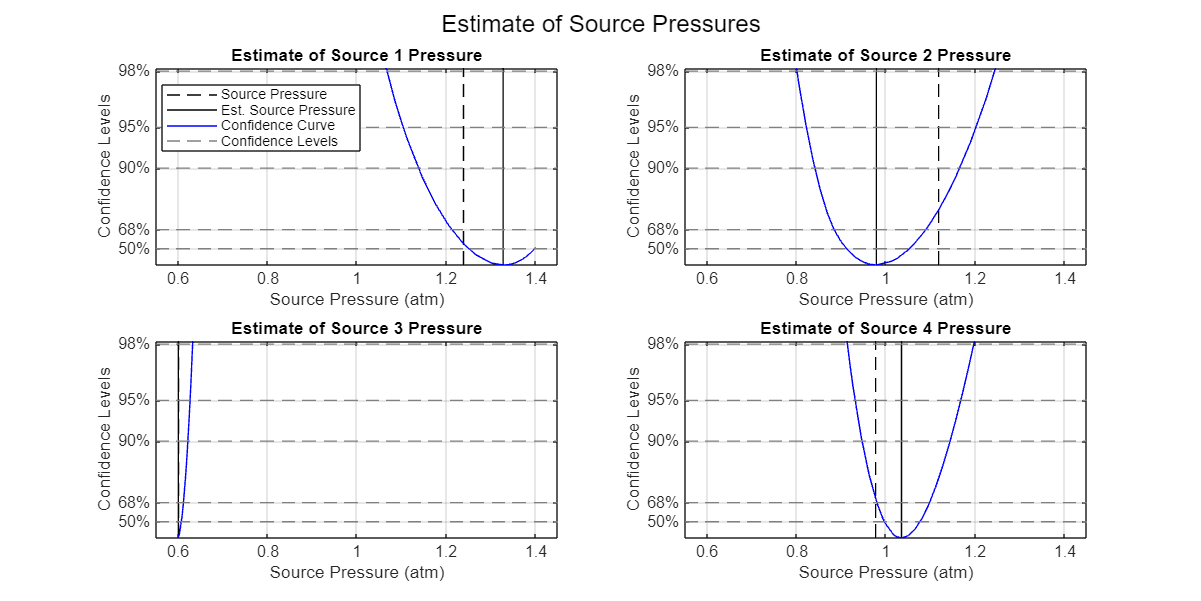


% Add path
addpath("./Surrogate Models")
addpath("./Utilities/")
addpath("Parameter Estimation\")

% Load Surrogate Model
if ~exist('parameter_small_mlp','var')
    load('./Surrogate Models/small_model.mat');
end

% Get random inputs and sensor readings
x = getRandomInputs(source_pressure,numSamples);
samples_ = small_scale_inference(x, parameter_small_mlp);
knownInputs = x([1,2:2:8],:); %extract collector pressure and pump speeds
sensorReadings = samples_(:,outputIdx) + randn(size(samples_,1),numel(outputIdx)).*sigma; % noise-up sensor readings

if isempty(outputIdx)
    disp('Select at least one sensor to use.')
else
    
    [V,S] = profileLikelihood(knownInputs,sensorReadings,source_pressure,outputIdx,sigma);
end

### Step 2: Compute Source Pressure Set

Once the confidence intervals are found, a set $\bar{P}_\alpha

$ can be constructed. A set of the specified size is computed in which members fall within the specified confidence level. We plot the gathered set for visual inspection.  

sizeSet = 5000;
confidenceLevel = 0.95;
 

%Use confidence bounds to determine search bounds
mins = zeros(4,1);
maxs = zeros(4,1);
for idx = 1:4
    [v,I] = sort(V(:,idx));
    s = S(I,idx)-min(S(I,idx))-chi2inv(confidenceLevel,1);
    lengthofside = floor(numel(v)/2);
    
    %remove any non-unique scores and interpolate
    [s_,IA] = unique(s(1:lengthofside));
    v_ = v(1:lengthofside);
    v_ = v_(IA);
    mins(idx) = interp1(s_,v_,0,[],0.6);
    [s_,IA] = unique(s(end-lengthofside:end));
    v_ = v(end-lengthofside:end);
    v_ = v_(IA);
    maxs(idx) = interp1(s_,v_,0,[],1.4);
end

% Set \bar{P}_\alpha
randSample = zeros(sizeSet,4);
idx = 1;
while 1
    randS = rand(1,4).*(maxs'-mins') + mins';
    s = getScore(randS,parameter_small_mlp,knownInputs,sensorReadings',sigma,outputIdx) - min(S,[],'all');
    if s<chi2inv(confidenceLevel,4)
        randSample(idx,:) = randS;
        idx = idx + 1;
        if idx>sizeSet
            break
        end
    end
end

disp(['Set of size ' num2str(sizeSet) ' and confidence level ' num2str(confidenceLevel) ' generated!'])

Set of size 5000 and confidence level 0.95 generated!


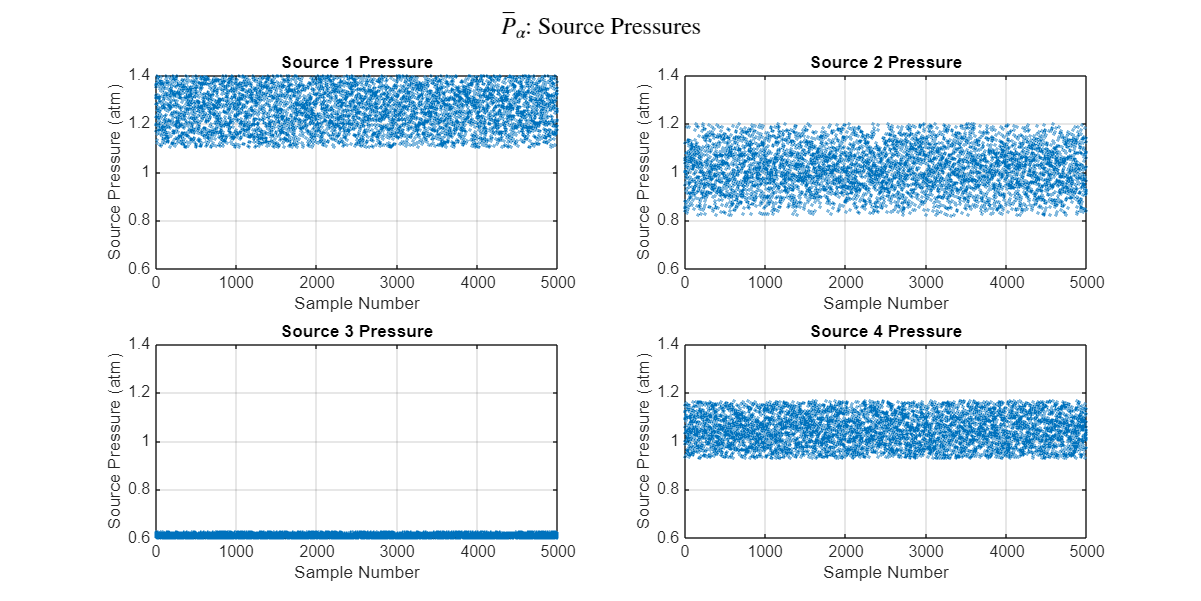


figure
set(gcf, 'Position', [100, 100, 1000, 500])
for idx = 1:4
    subplot(2, 2, idx);
    scatter(1:sizeSet,randSample(:,idx), 2)
    ylim([0.6,1.4])
    title(['Source ' num2str(idx) ' Pressure'])
    xlabel('Sample Number')
    ylabel('Source Pressure (atm)')
    box on 
    grid on
end 
sgtitle('$\bar{P}_\alpha$: Source Pressures','interpreter','latex')

### Step 3: Optimize over Source Pressure Set and Validate Performance

The optimization framework described above is executed. The plots below display the expected performance of the optimized system with a specific confidence level.

In addition, a validation set $\bar{P}_{\alpha}^{v}

$ is constructed to validate the optimization results. Note that $\bar{P}_{\alpha}


$ and $\bar{P}_{\alpha}^{v}

$ need not have the same size or confidence level. However, the validation will only make sense if the confidence level of $\bar{P}_{\alpha}^{v}

$ is equal to or less than the confidence level of $\bar{P}_{\alpha}


$.

powerLimit = 2000;
vald_sizeSet = 5000;
vald_confidenceLevel = 0.95;
 

%add paths
addpath("./Optimization/")

[x_opt,minFlow] = optimization(randSample,powerLimit);

Optimization beginning....
Optimization done....



disp('Creating Validation Set.')

Creating Validation Set.


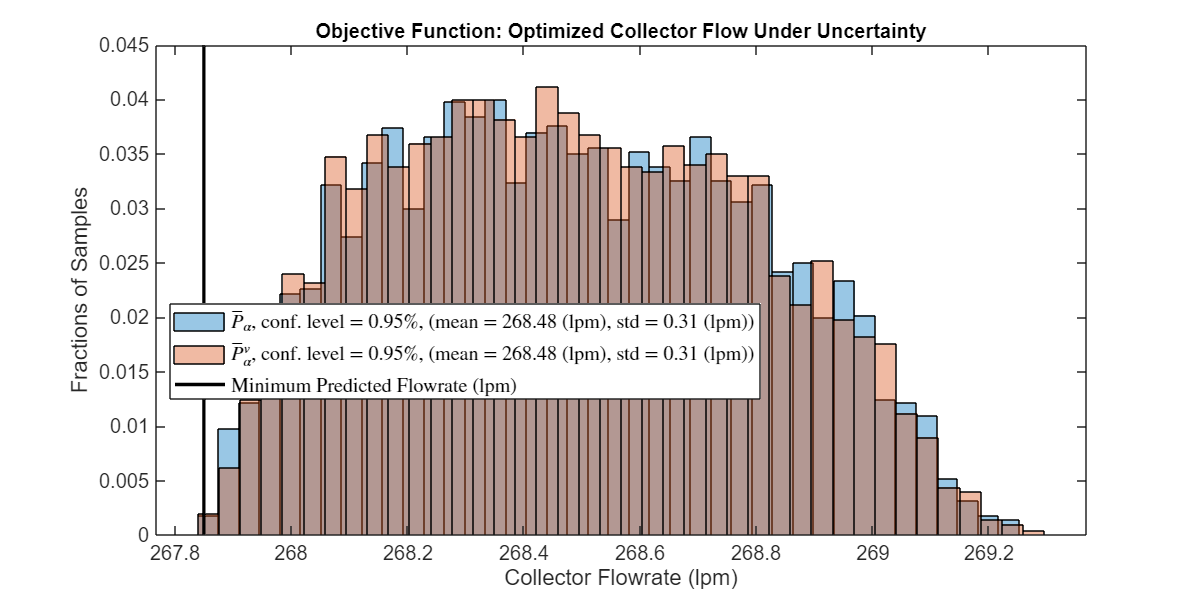


%Use confidence bounds to determine search bounds
mins = zeros(4,1);
maxs = zeros(4,1);
for idx = 1:4
    [v,I] = sort(V(:,idx));
    s = S(I,idx)-min(S(I,idx))-chi2inv(confidenceLevel,1);
    lengthofside = floor(numel(v)/2);
    
    %remove any non-unique scores and interpolate
    [s_,IA] = unique(s(1:lengthofside));
    v_ = v(1:lengthofside);
    v_ = v_(IA);
    mins(idx) = interp1(s_,v_,0,[],0.6);
    [s_,IA] = unique(s(end-lengthofside:end));
    v_ = v(end-lengthofside:end);
    v_ = v_(IA);
    maxs(idx) = interp1(s_,v_,0,[],1.4);
end

% Set \bar{P}_\alpha^v
vald_randSample = zeros(vald_sizeSet,4);
idx = 1;
while 1
    randS = rand(1,4).*(maxs'-mins') + mins';
    s = getScore(randS,parameter_small_mlp,knownInputs,sensorReadings',sigma,outputIdx) - min(S,[],'all');
    if s<chi2inv(vald_confidenceLevel,4)
        vald_randSample(idx,:) = randS;
        idx = idx + 1;
        if idx>sizeSet
            break
        end
    end
end

inputs = completeInput(x_opt,randSample);
vald_inputs = completeInput(x_opt,vald_randSample);

samples = small_scale_inference(inputs, parameter_small_mlp);
vald_samples = small_scale_inference(vald_inputs, parameter_small_mlp);

% create collector flow rate histograms
fig = figure;
set(gcf, 'Position', [100, 100, 1000, 500])
numBins = 40;
h = histogram(samples(:,1), numBins, 'FaceAlpha', 0.4, 'EdgeColor', 'k','Normalization','probability');
hold on;
h = histogram(vald_samples(:,1), numBins, 'FaceAlpha', 0.4, 'EdgeColor', 'k','Normalization','probability');
plot([minFlow,minFlow],[0,fig.CurrentAxes.YLim(2)],'k','LineWidth',2)
title('Objective Function: Optimized Collector Flow Under Uncertainty','FontSize',12);
xlabel('Collector Flowrate (lpm)','FontSize',12);
ylabel('Fractions of Samples','FontSize',12);
legend(['$\bar{P}_\alpha$, conf. level = ' num2str(confidenceLevel) '\%, (mean = ' num2str(round(mean(samples(:,1)),2)) ' (lpm), std = ', num2str(round(std(samples(:,1)),2)),' (lpm))'],...
    ['$\bar{P}_\alpha^v$, conf. level = ' num2str(vald_confidenceLevel) '\%, (mean = ' num2str(round(mean(vald_samples(:,1)),2)) ' (lpm), std = ', num2str(round(std(vald_samples(:,1)),2)),' (lpm))'],...
    'Minimum Predicted Flowrate (lpm)',...
    'FontSize',12,'Location','best','interpreter', 'latex');
hAx = gca;
hAx.XAxis.FontSize = 12;
hAx.YAxis.FontSize = 12;

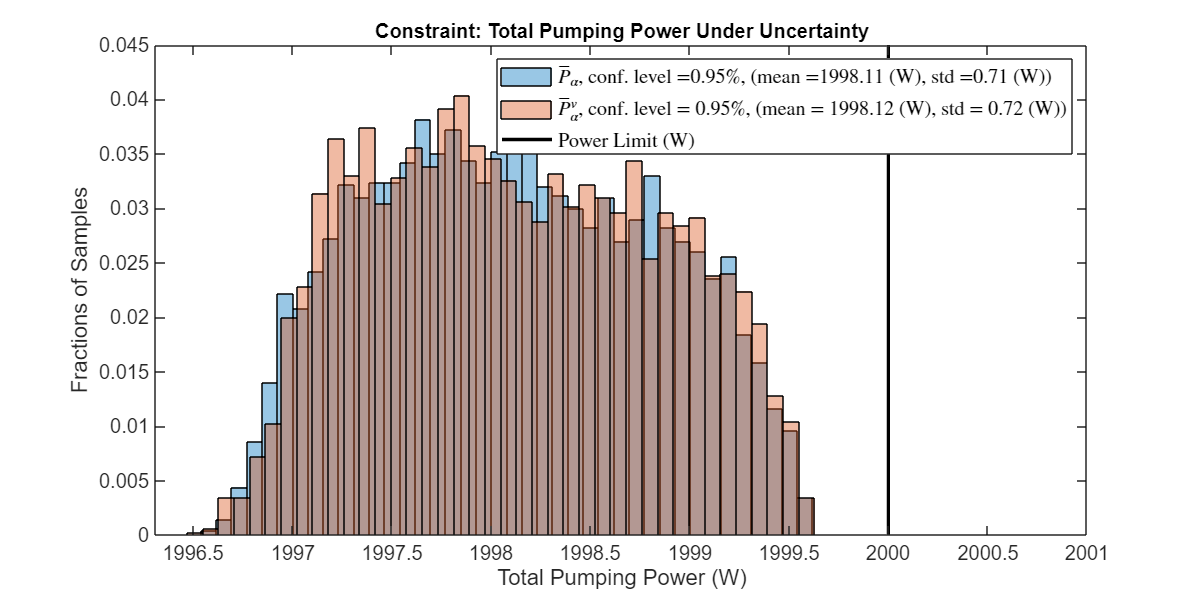


% create pumping power histograms
fig = figure;
set(gcf, 'Position', [100, 100, 1000, 500])
numBins = 40;
h = histogram(-1*sum(samples(:,[4,7,10,13]),2), numBins, 'FaceAlpha', 0.4, 'EdgeColor', 'k','Normalization','probability');
hold on;
h = histogram(-1*sum(vald_samples(:,[4,7,10,13]),2), numBins, 'FaceAlpha', 0.4, 'EdgeColor', 'k','Normalization','probability');
plot([powerLimit,powerLimit],[0,fig.CurrentAxes.YLim(2)],'k','LineWidth',2)
title('Constraint: Total Pumping Power Under Uncertainty','FontSize',12);
xlabel('Total Pumping Power (W)','FontSize',12);
ylabel('Fractions of Samples','FontSize',12);
legend(strcat('$\bar{P}_\alpha$, conf. level = ',num2str(confidenceLevel),'\%, (mean = ',num2str(round(mean( -1*sum(samples(:,[4,7,10,13]),2) ),2)),' (W), std = ', num2str(round(std( -1*sum(samples(:,[4,7,10,13]),2) ),2)),' (W))'),...
    ['$\bar{P}_\alpha^v$, conf. level = ' num2str(vald_confidenceLevel) '\%, (mean = ' num2str(round(mean( -1*sum(vald_samples(:,[4,7,10,13]),2) ),2)) ' (W), std = ', num2str(round(std( -1*sum(vald_samples(:,[4,7,10,13]),2) ),2)),' (W))'],...
    'Power Limit (W)',...
    'FontSize',12,'Location','best','interpreter', 'latex');
hAx = gca;
hAx.XAxis.FontSize = 12;
hAx.YAxis.FontSize = 12;

xlim_ = xlim;
if xlim_(2) < powerLimit + 1
    xlim([xlim_(1), xlim_(2)+1])
end

## Affect of Parameter Estimation Quality

As mentioned previously, parameter estimation quality directly affects the quality of the optimized solutions. We have compared two scenarios to illustrate this point. The figures below display results from two different scenarios. In the first scenario, five sensor samples are gathered, with noise models for the flow meter and pressure sensors specified as $$\mathcal{N}(0,1.5^2)$$ (lpm) and $$\mathcal{N}(0,0.2
^2)$$ (kPa), respectively. In the second, twenty sensor samples are gathered, with noise models for the flow meter and pressure sensors specified as $$\mathcal{N}(0,0.25^2)$$ (lpm) and $$\mathcal{N}(0,0.1^2)$$ (kPa), respectively.

The optimization conducted on the second scenario yielded a significantly more predictable system performance. Notably, the range of possible collector flow rates is much narrower. Furthermore, the spread of possible source pressures in set $\bar{P}_{\alpha}


$ is considerably narrower in the second scenario. However, it's crucial to note that the validation sets for both cases demonstrated the optimization framework's ability to consistently deliver predictable results that satisfied the given constraints. 

### Scenario 1: Lower Accuracy Parameter Estimation

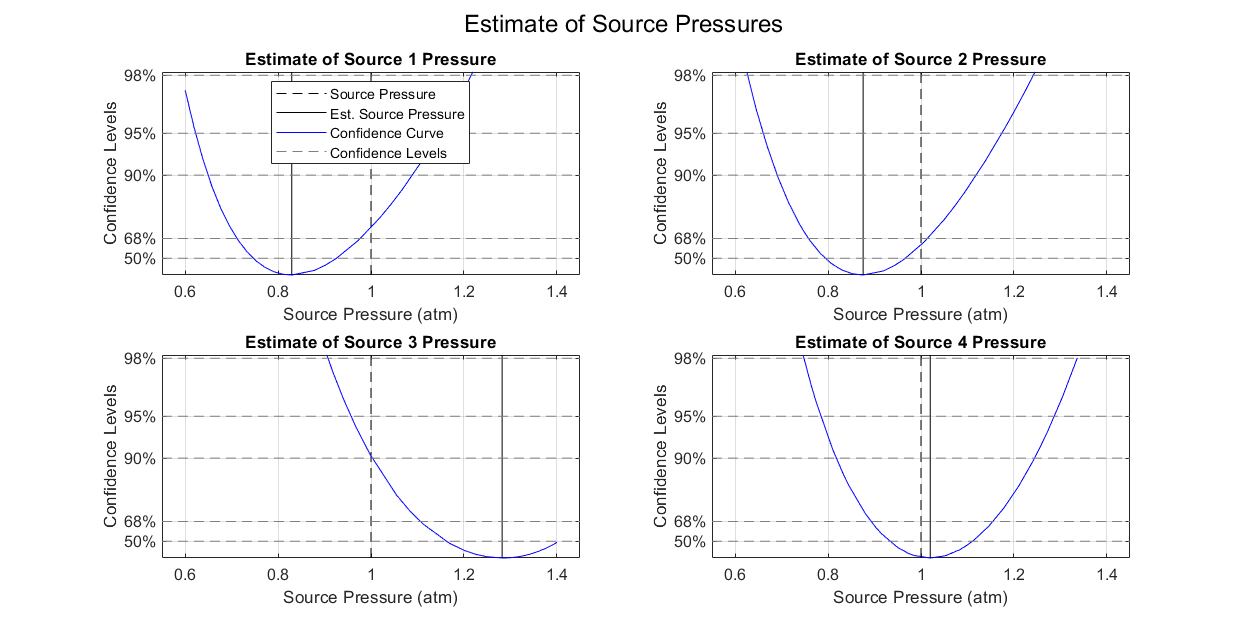

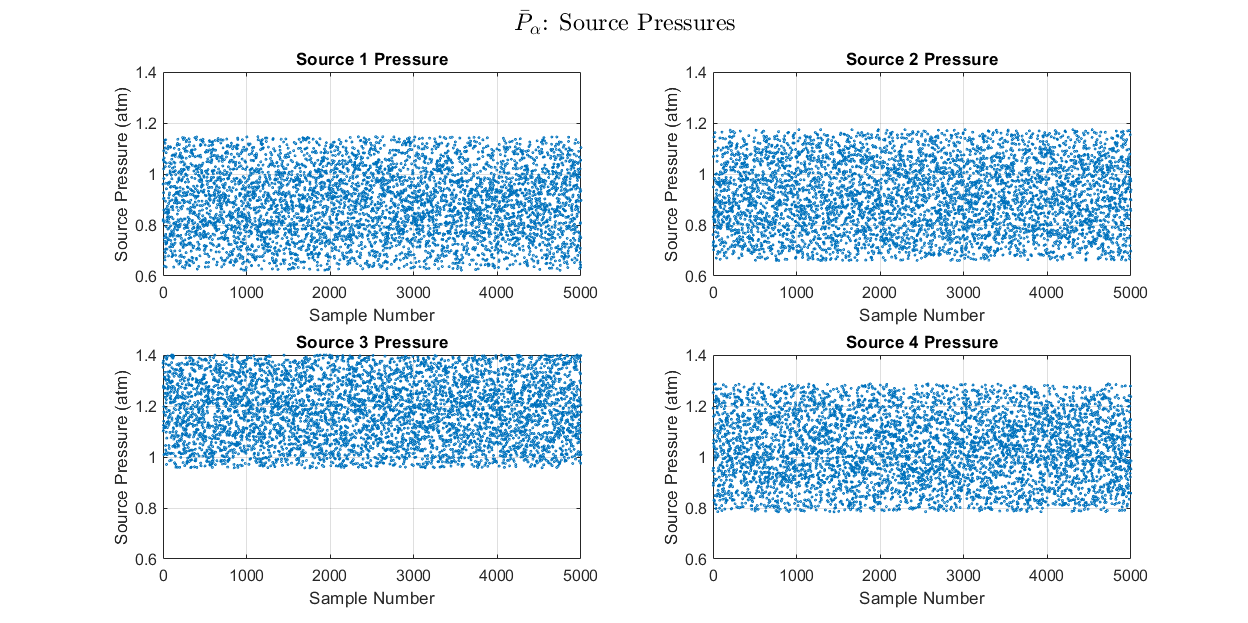

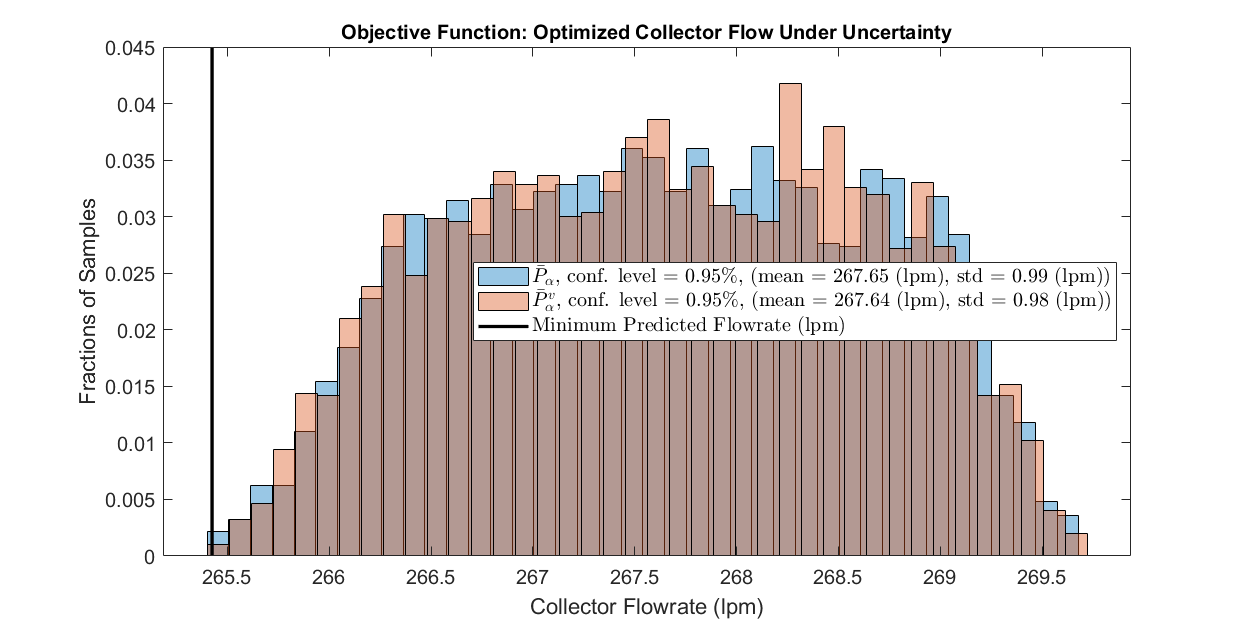

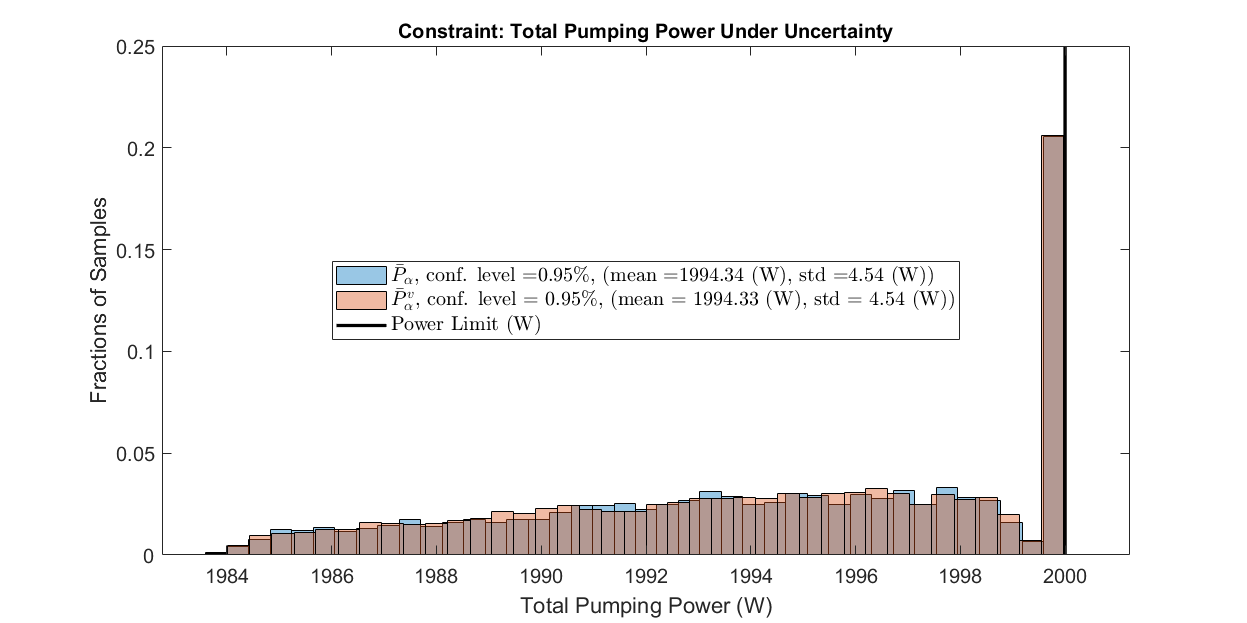

### Scenario 2: Higher Accuracy Parameter Estimation

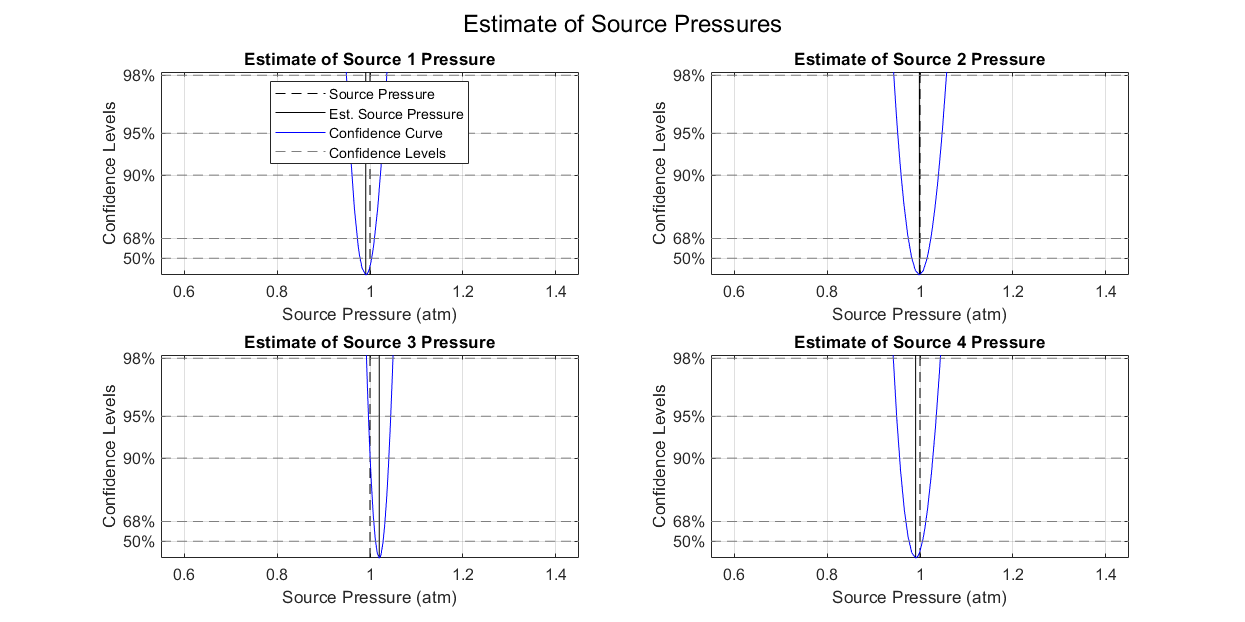

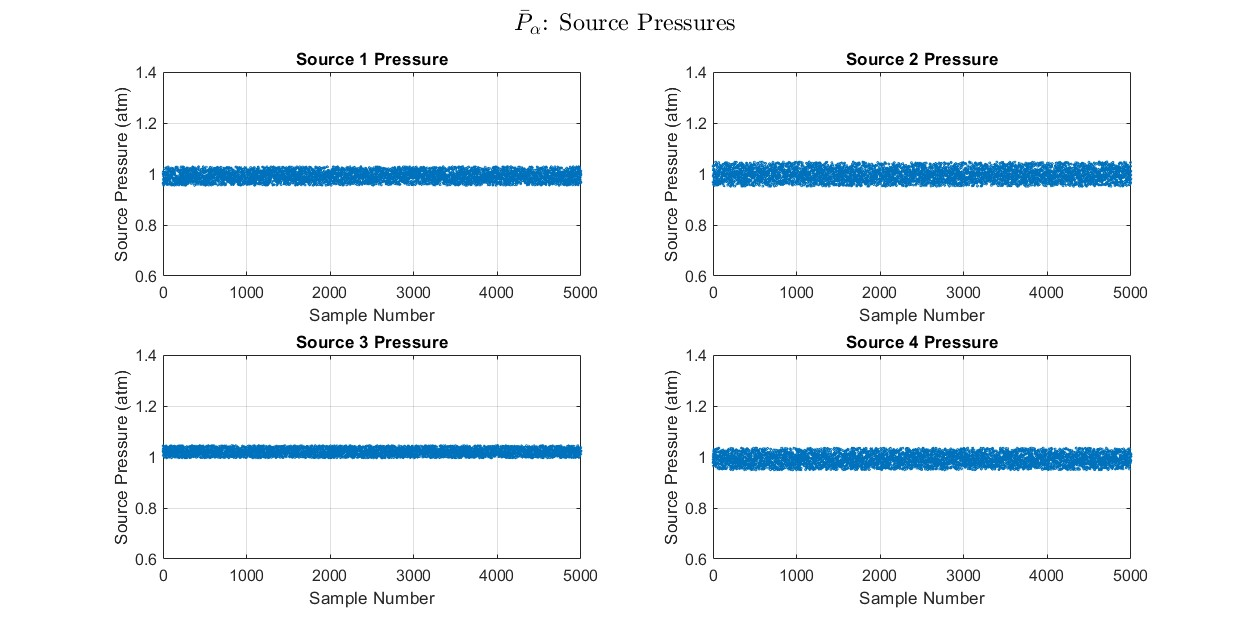

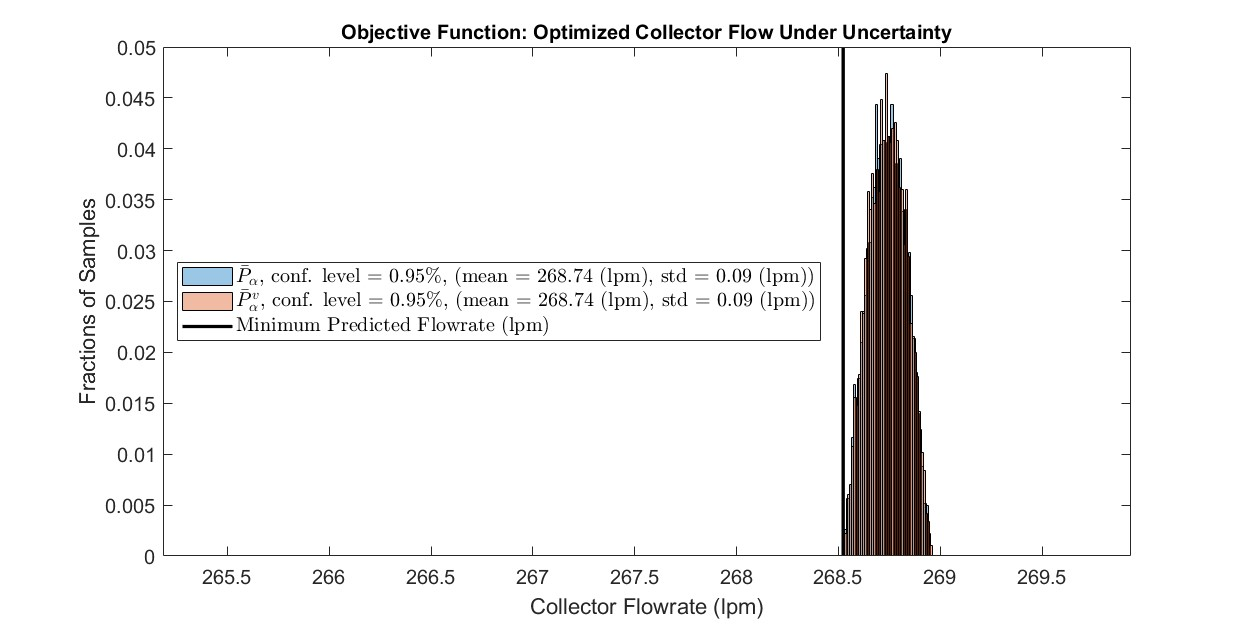

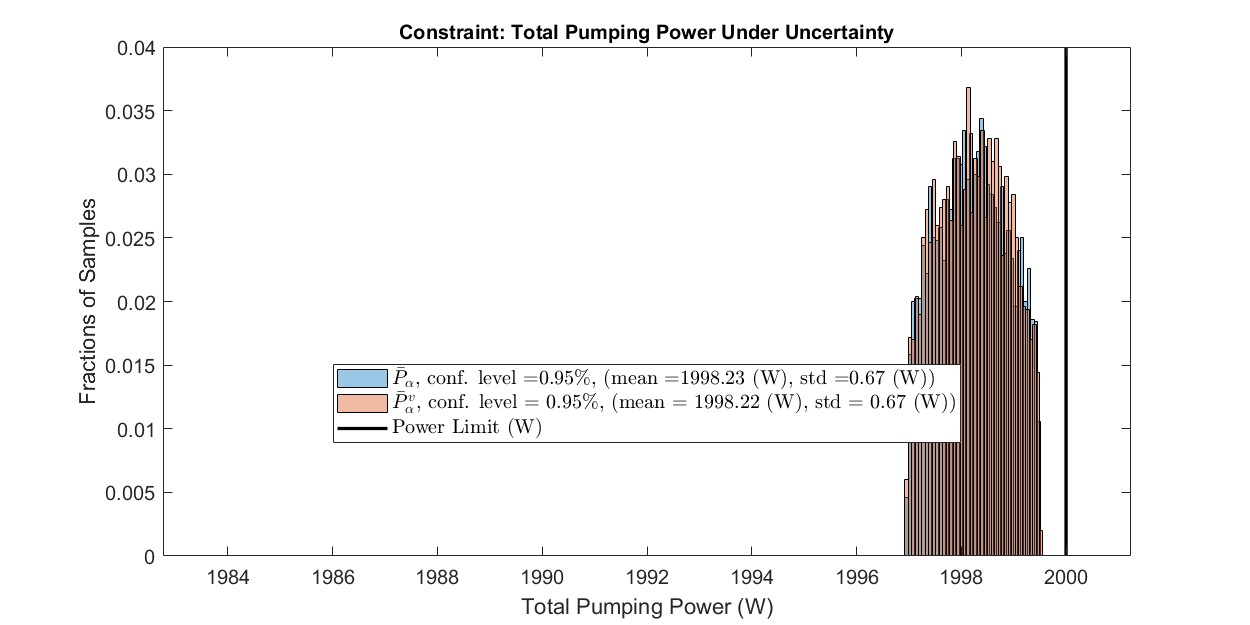

## Summary

We join the parameter estimation approach introduced in Parameter Estimation via Profile Likelihoods and the surrogate model-based optimization framework discussed in Surrogate Model-Based Optimization to achieve an optimization solution under uncertain modeling parameters. Specifically, we explicitly use the parameter estimation's confidence intervals to perform constrained optimization over a distribution of possible outcomes. As shown for other workflows, surrogate models and surrogate model-based optimization techniques are the critical enablers for this approach. 

## References

- [Royston, Patrick. "Profile likelihood for estimation and confidence intervals." *The Stata Journal* 7.3 (2007): 376-387.](https://journals.sagepub.com/doi/pdf/10.1177/1536867X0700700305)